c =   -0.2500 + 0.0000i
   0.5000 + 0.0000i
  -0.0000 - 0.0000i
   0.5000 + 0.0000i
   0.2500 - 0.0000i


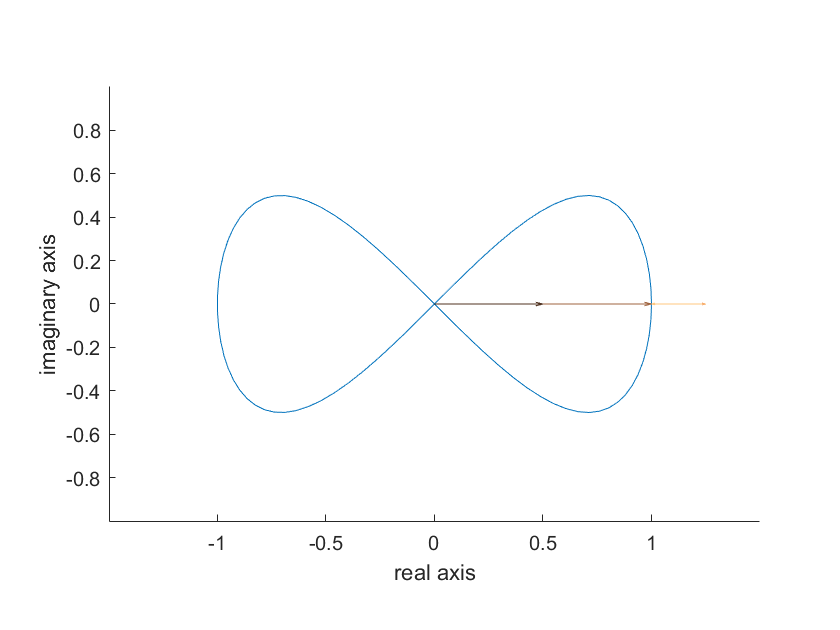

Nm = 2; % The number of modes is (2Nm+1)
Ncycles = 2;
Nt = 90;
showCircles = false;
showConstantMode = true;
 

complexFourierArrows(Nt,Nm,Ncycles,showCircles,showConstantMode);

function [x,y] = squareFunc(t)
    % Periodic on (0,1)
    t = mod(t,1);
    % Square parameterized by t
    x = 0*(t < 0.25) + (t-0.25)*4.*((0.25<=t)&(t<0.5)) + ...
        + ((0.5<=t)&(t<0.75)) +  (1 - (t-0.75)*4).*(t >= 0.75);
    y = t*4.*(t < 0.25) + ((0.25<=t)&(0.5>t)) + ...
        + (1-(t-0.5)*4).*((0.5<=t)&(t<0.75)) + 0*(t >= 0.75);
end

function [x,y] = figure8(t)

    tscaled = t*2*pi;
    x = cos(tscaled);
    y = sin(tscaled).*cos(tscaled);
end

function [c,basis,f_approx] = complexFourier(Nmodes, Nt, t, f)
    % Compute the fourier basis and coefficients
    c = zeros(Nmodes*2+1,1);
    basis = zeros(Nmodes*2+1,Nt);
    for n = -Nmodes:Nmodes
        nIdx = n + Nmodes + 1;
        basis(nIdx,:) = exp(-n*2*pi*1i*t);
        f_approx = f.*basis(nIdx,:);
        % Integrate to find the coefficients
        c(nIdx) = (t(2)-t(1))*trapz(f_approx);
    end
    % Approximation of the fourier series
    f_approx = sum(c.*basis);
end


function complexFourierArrows(Nt,Nm,Ncycles,showCircles,showConstantMode)
    % The number of modes is (2Nm+1)

    t = linspace(0,1,Nt);
%     [x,y] = squareFunc(t);
    [x,y] = figure8(t);
    f = x+y*1i;
    [c,basis,fApprox] = complexFourier(Nm, Nt, t, f);
    c
    colors = copper(2*Nm+1);
    fColor = [0,0.447,.741];
    fColorFade = [0.75,0.8,0.85];


    figure
    ax = axes;
    hold(ax,"on")
    plot([fApprox,fApprox(1)],'color',fColor)
    plot([f,f(1)],'-','color',fColorFade)
    fHandle = plot(0,0,'color',lines(1));
    for j = 1:(2*Nm+1)
        modeQuivers{j} = quiver(0,0,0,0,'off','color',colors(j,:));
        circHandles{j} = plot(ax,0,0,'color',colors(j,:));   
    end
    thetaCirc = linspace(0,2*pi,50);
    hold(ax,"off")
  
    % Compute and set axis limits
    flims = [min(real(fApprox)),max(real(fApprox)),min(imag(fApprox)),max(imag(fApprox))];
    delfx = flims(2)-flims(1);
    delfy = flims(2)-flims(1);
    lims = flims + [-delfx/4,delfx/4,-delfy/4,delfy/4];
    axis equal   
    axis(lims)
    xlabel('real axis')
    ylabel('imaginary axis')
    
    
    nSeq = [(1:Nm);-(1:Nm)];
    nOrder = [0;nSeq(:)]';
    nIdx = nOrder+Nm+1;

    for K = 1:Ncycles
        for k = 1:Nt
            fnStart = 0;
            for j = 1:(2*Nm+1)
                
                % Retrieve fourier values
                n = nOrder(j);
                nkBasis = basis(nIdx(j),k);
                cn = c(nIdx(j));
                fn = cn*nkBasis;
                
                if(j~=1 || showConstantMode)
                    % Show the quiver arrows
                    modeQuivers{j}.XData = real(fnStart);
                    modeQuivers{j}.YData = imag(fnStart);
                    modeQuivers{j}.UData = real(fn);
                    modeQuivers{j}.VData = imag(fn);
                    % Update the circle (if necessary)
                    if(showCircles)
                        updateCircle(circHandles{j},abs(fn),[real(fnStart),imag(fnStart)],thetaCirc)
                    end
                end
        
                % Update the arrow starting location
                fnStart = fnStart+fn;
                
            end
    
            % Update the plot of f
            fHandle.XData = real(fApprox(1:k));
            fHandle.YData = imag(fApprox(1:k));
    
            drawnow
        end
    end
end

function updateCircle(pHandle,r,c,theta)
    pHandle.XData = c(1) + r*cos(theta);
    pHandle.YData = c(2) + r*sin(theta);
end